k = 1

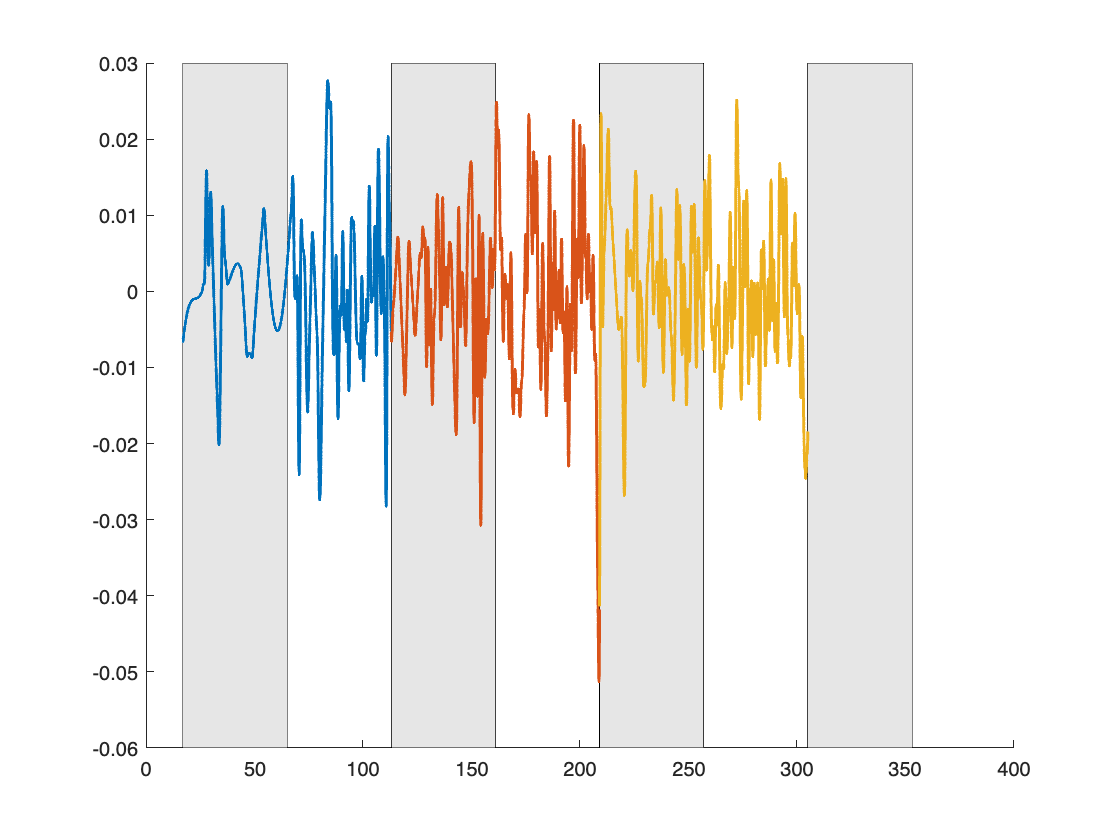

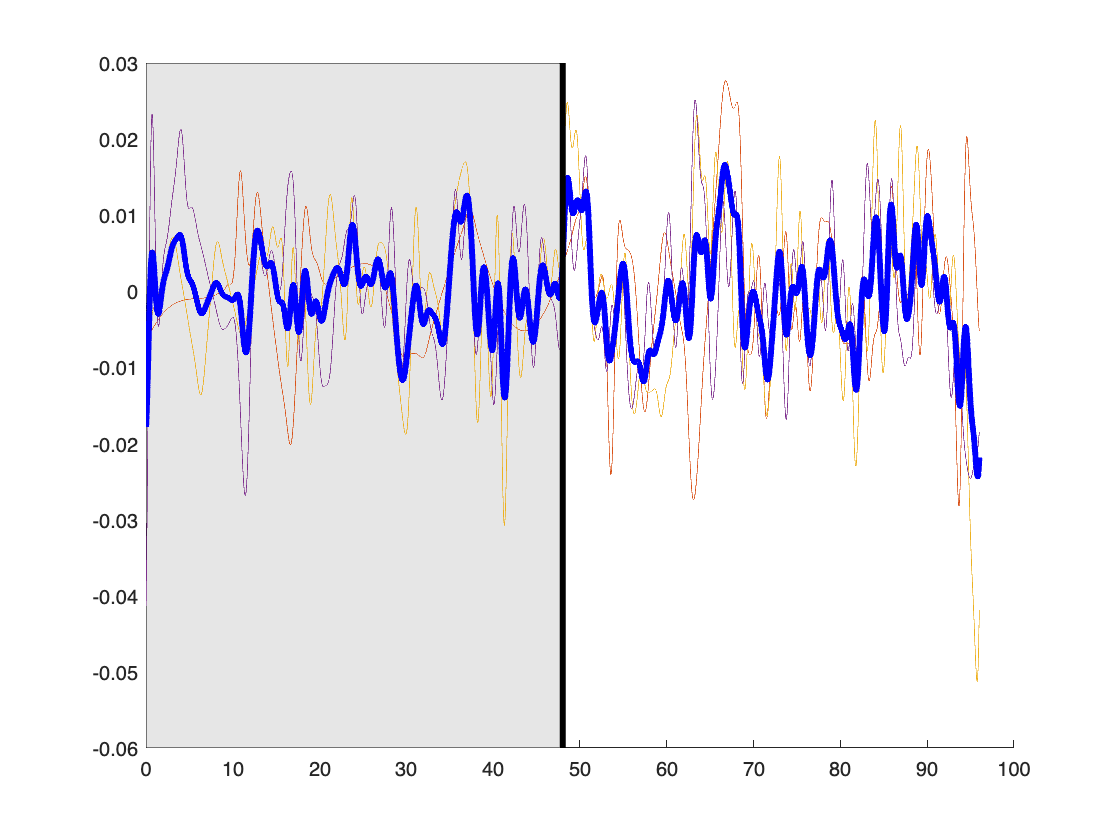

k = 2

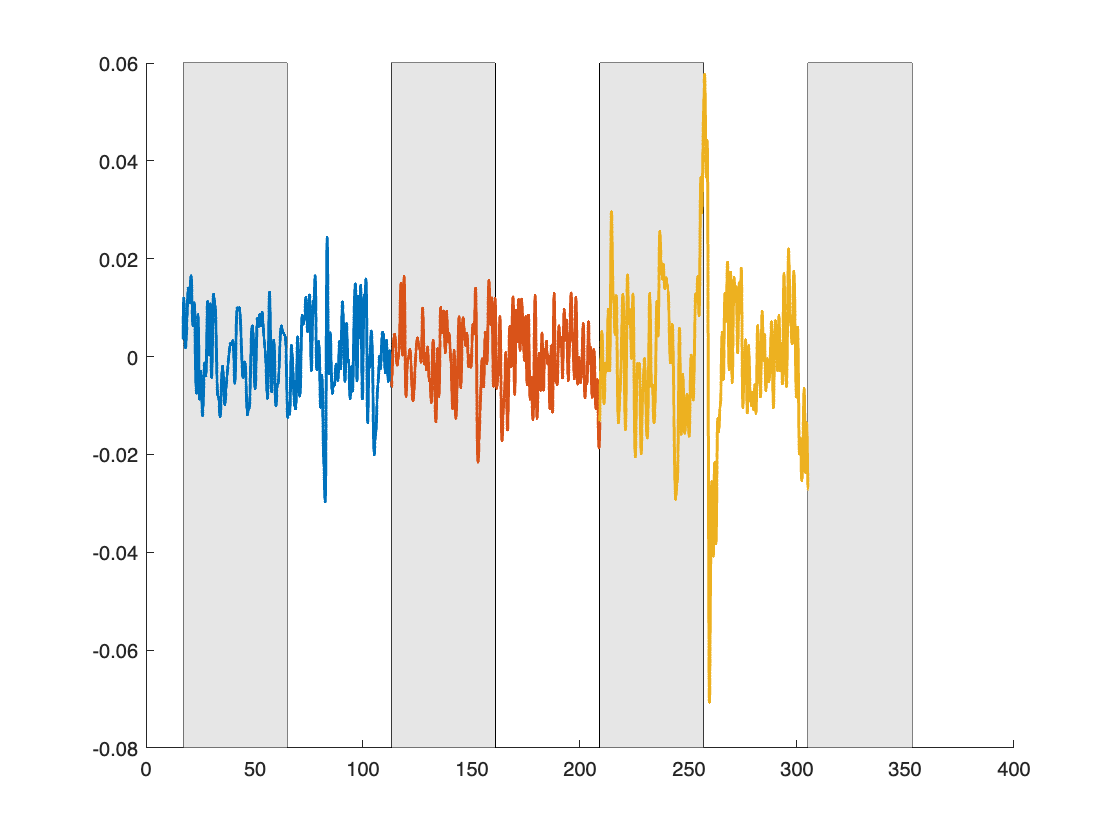

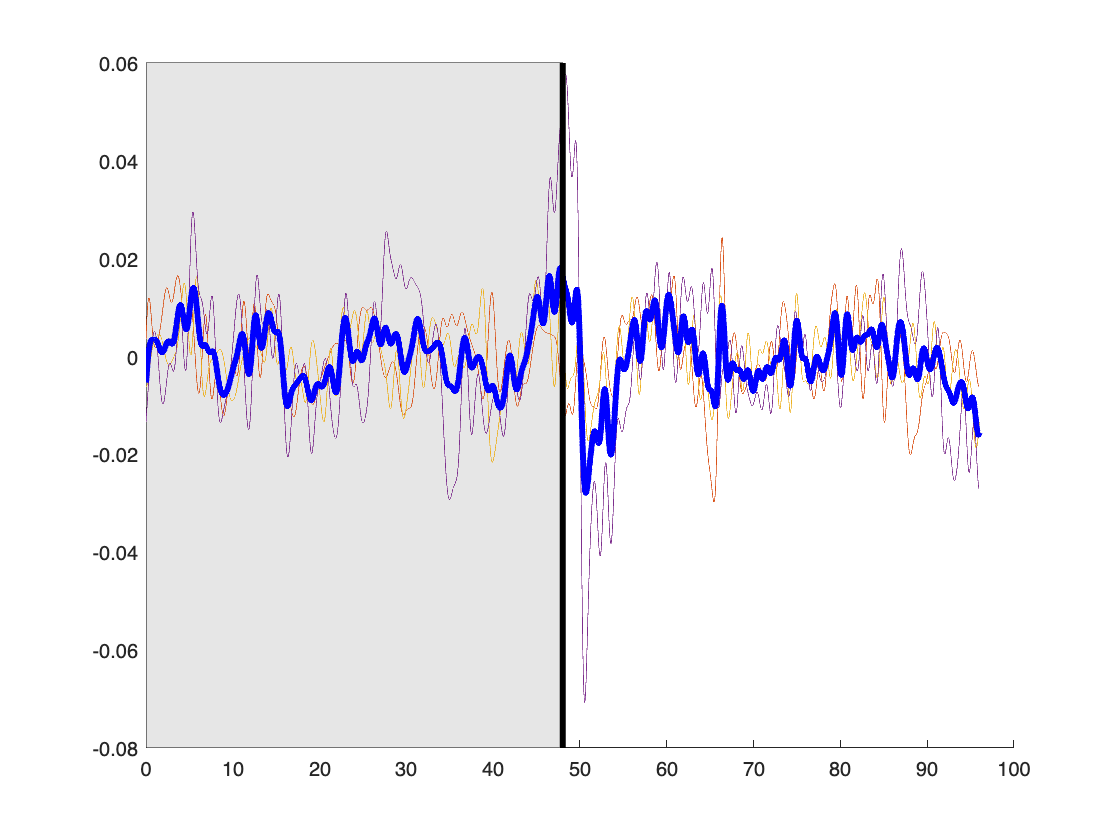

k = 3

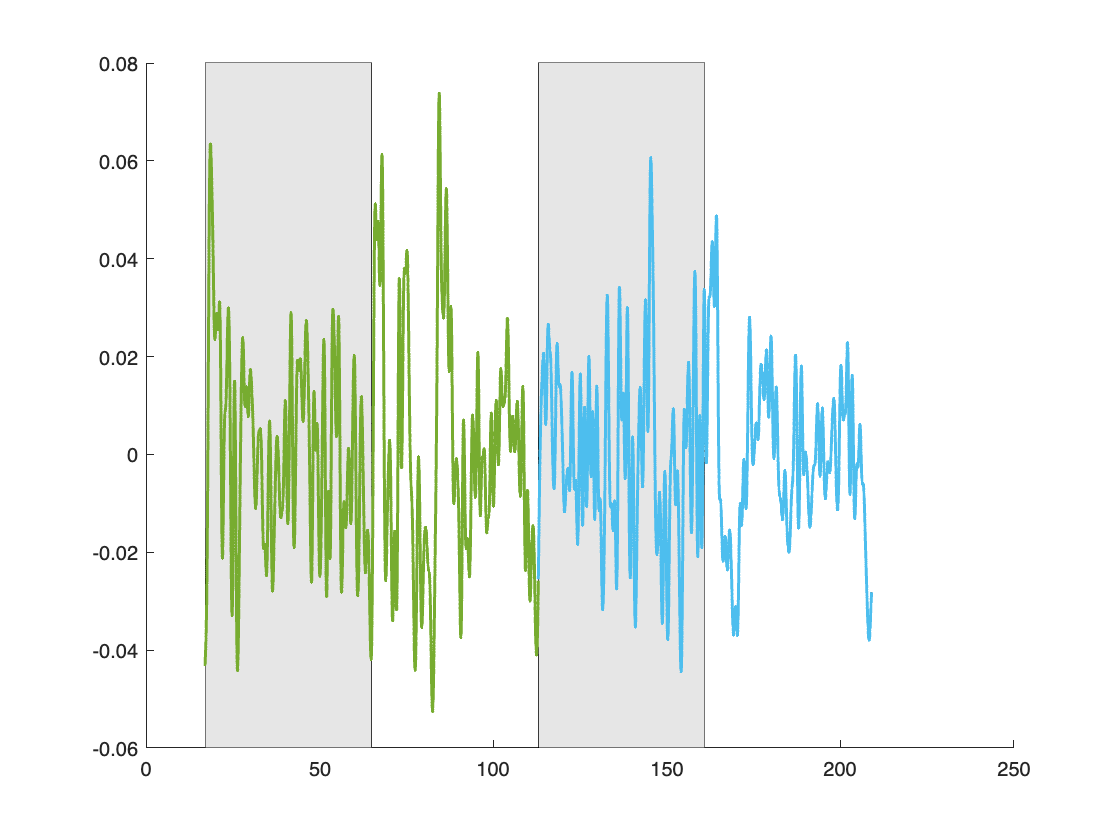

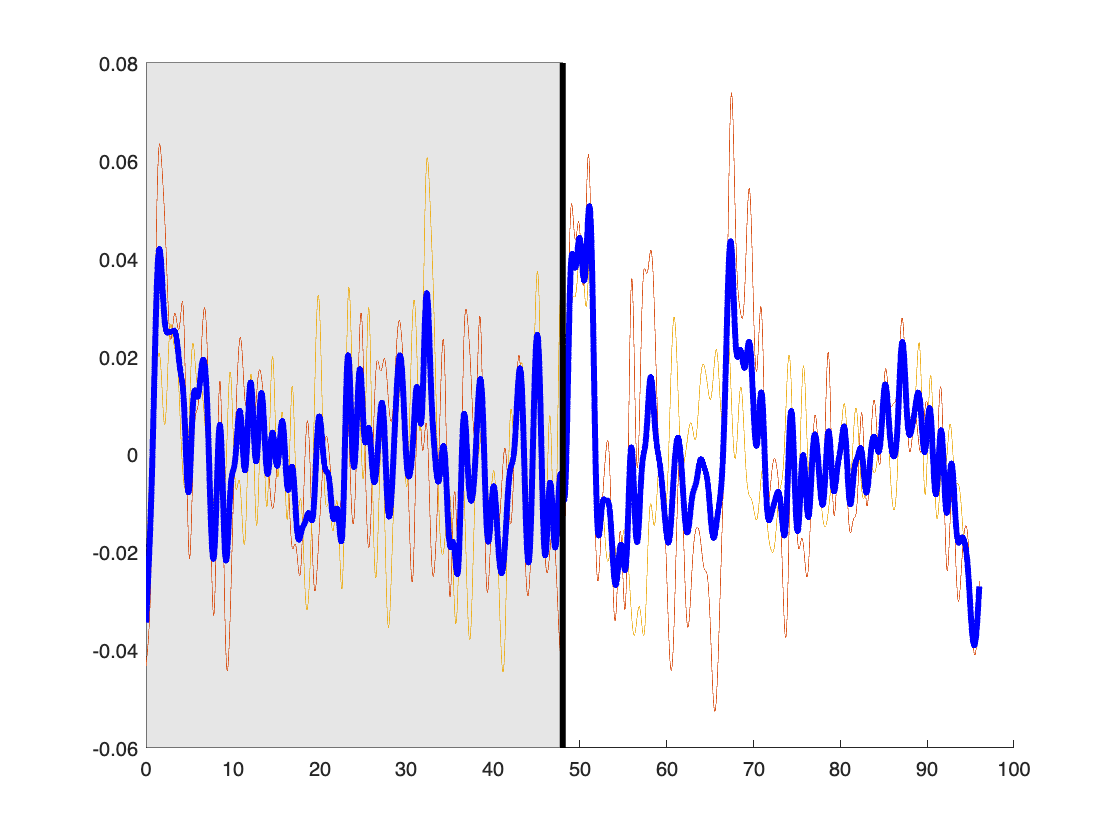

k = 4

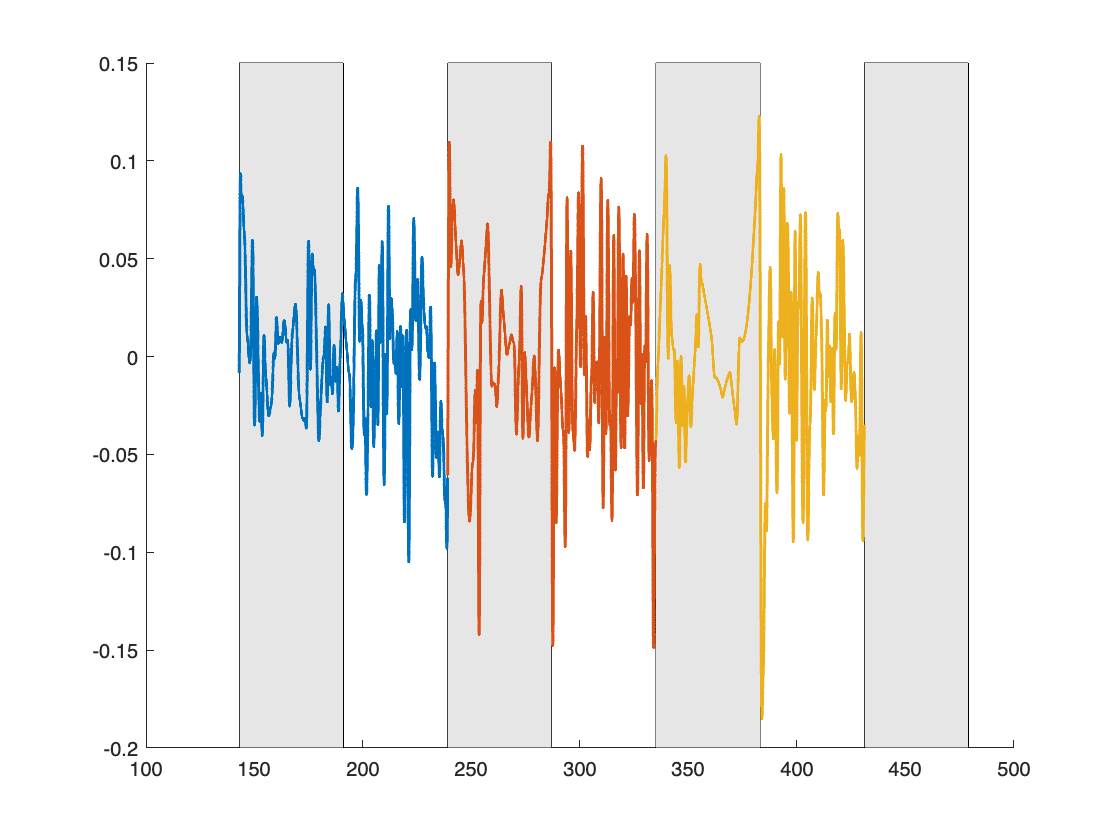

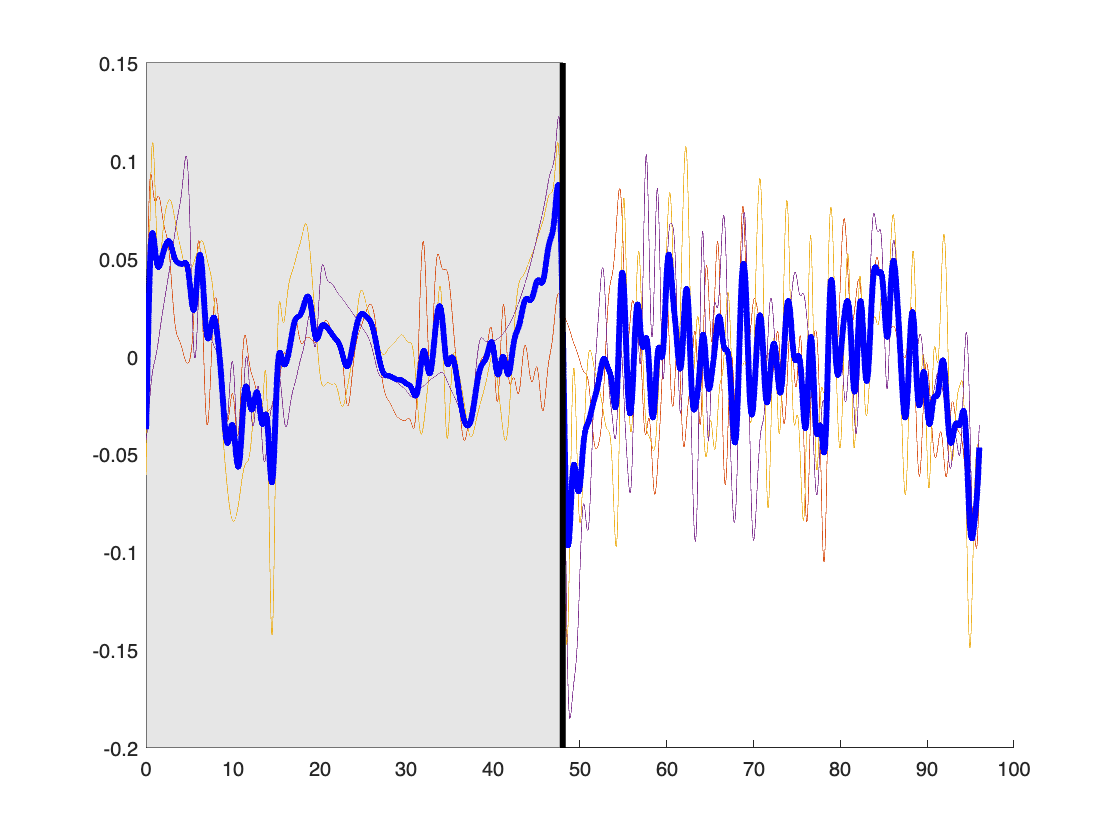

k = 5

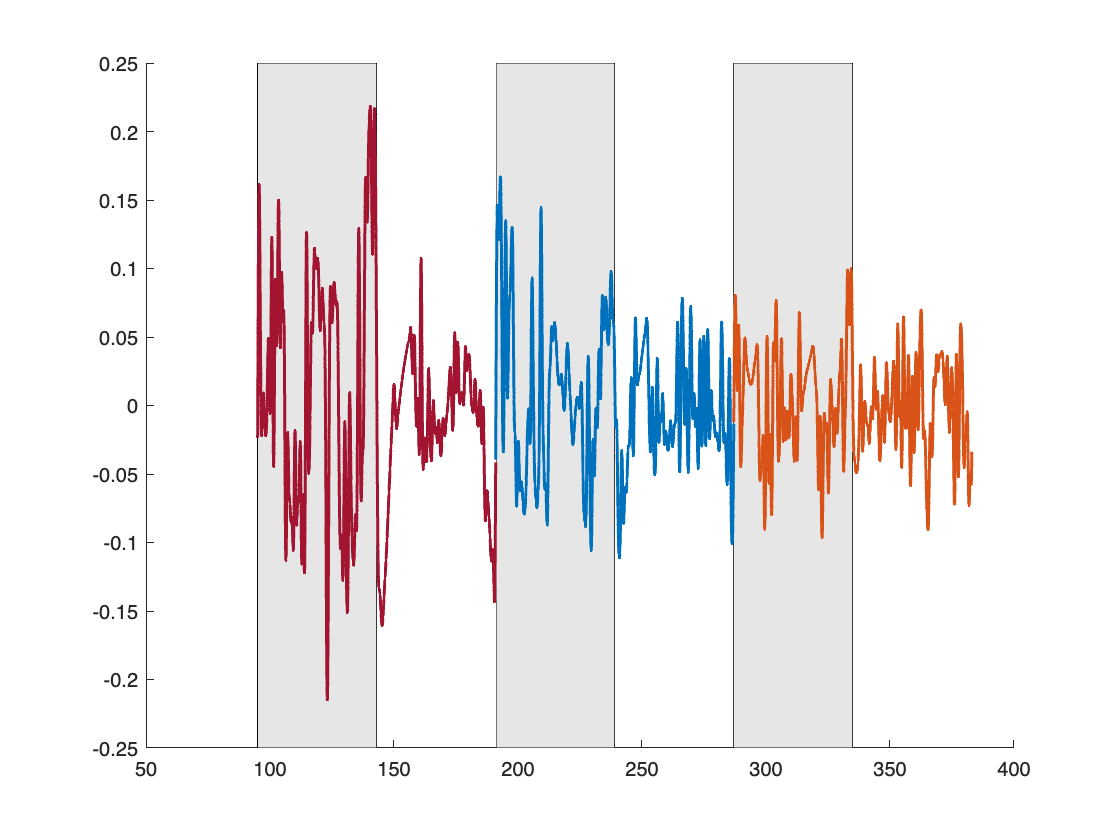

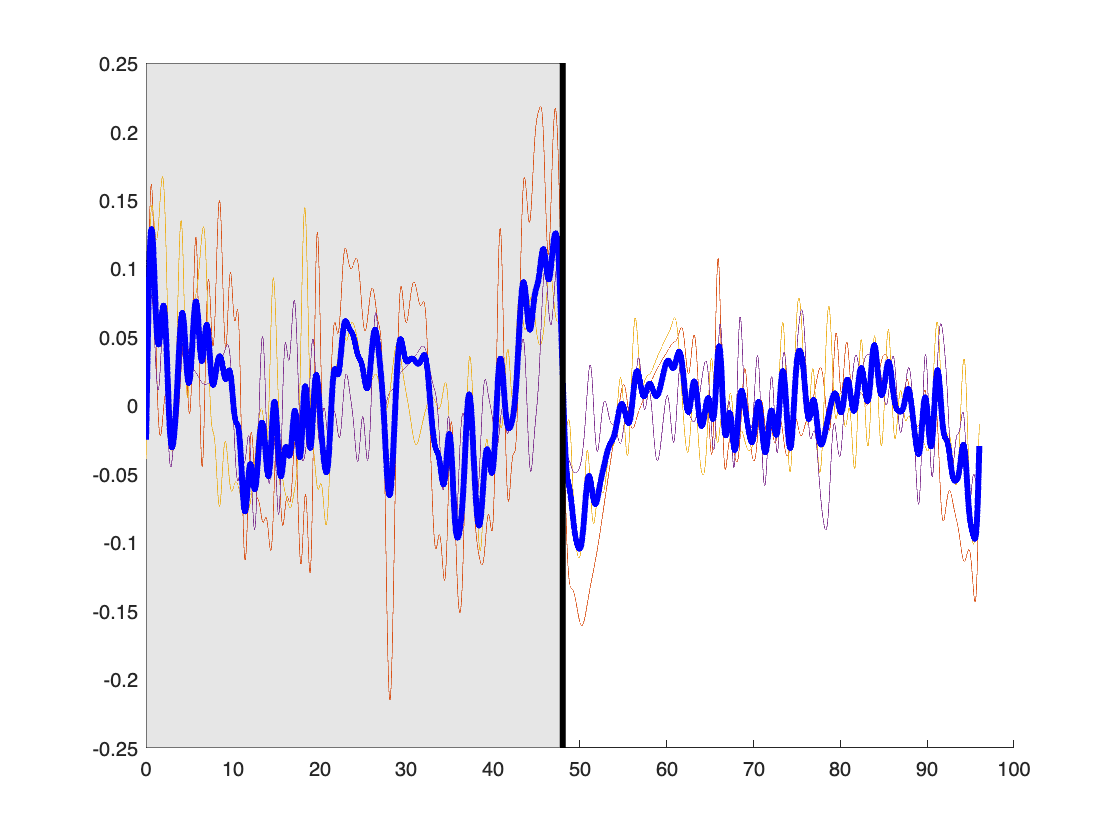

k = 6

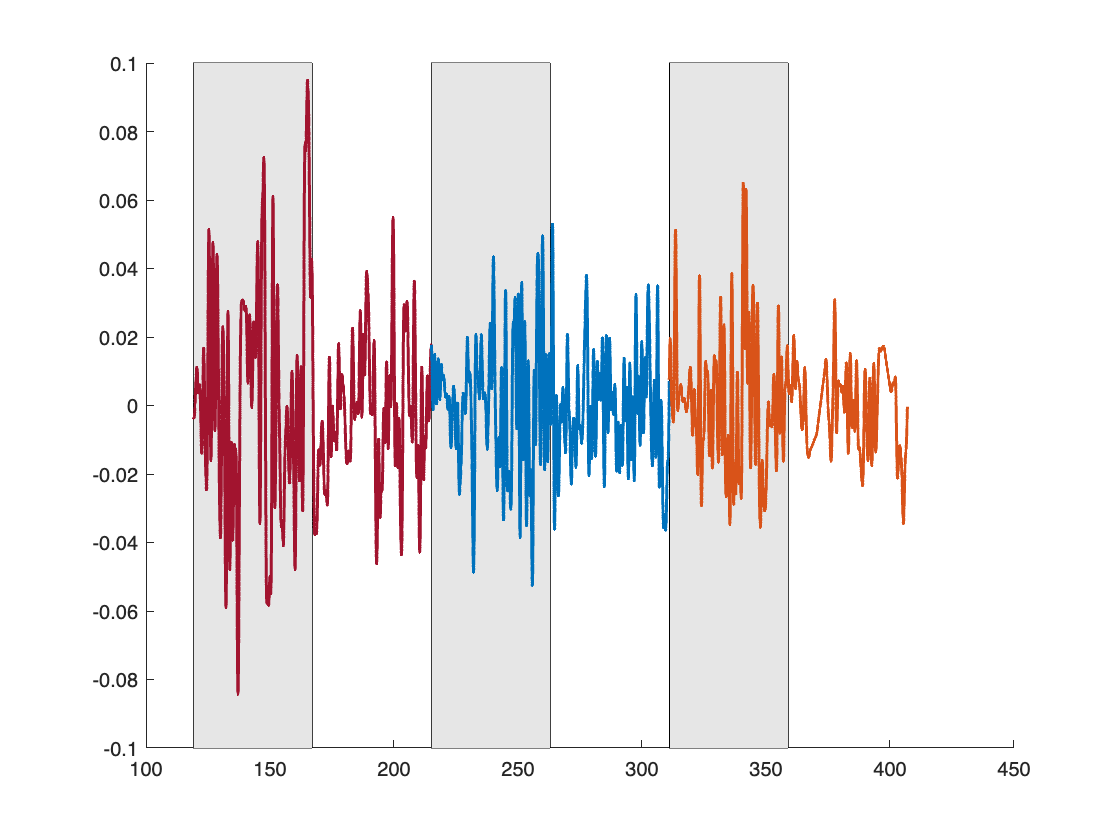

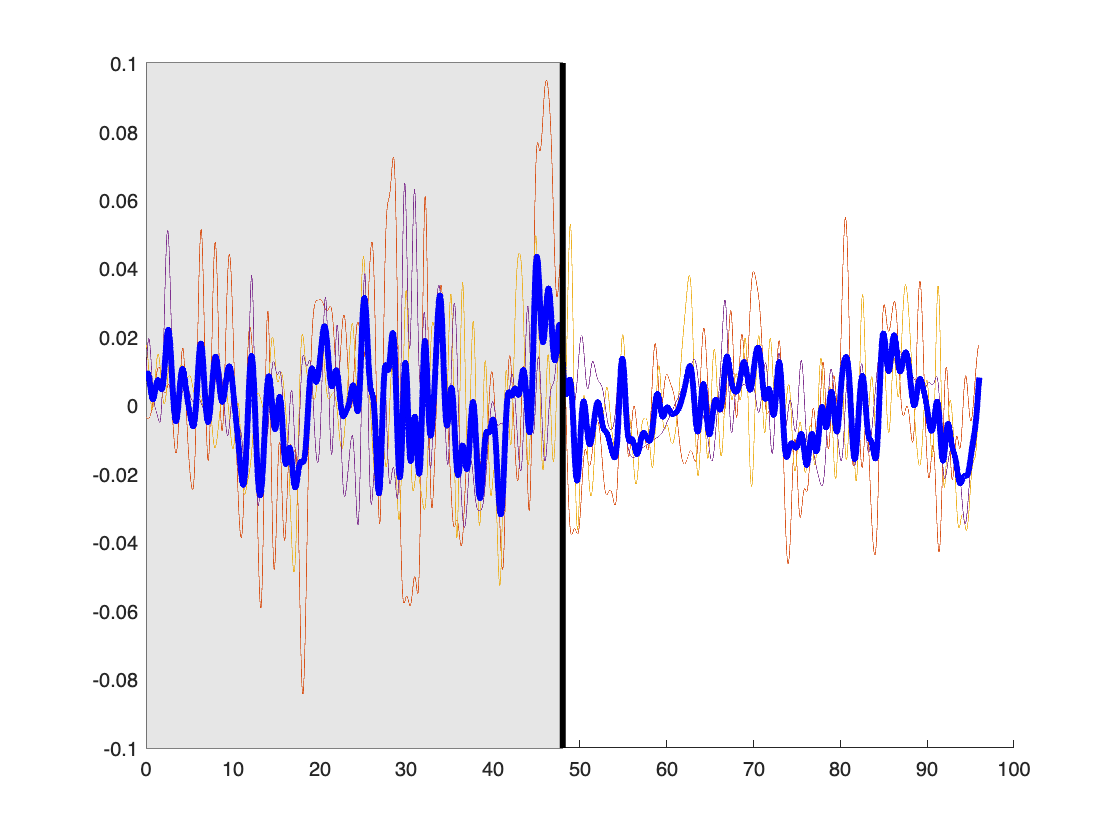

k = 7

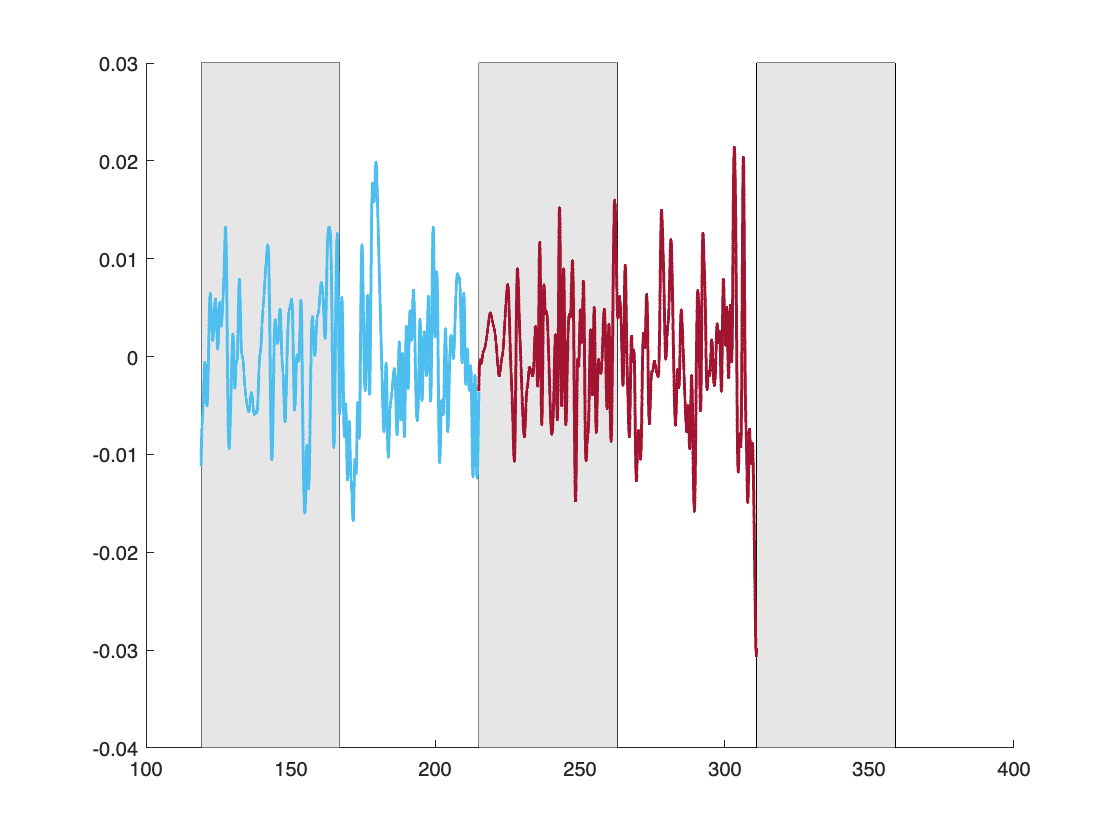

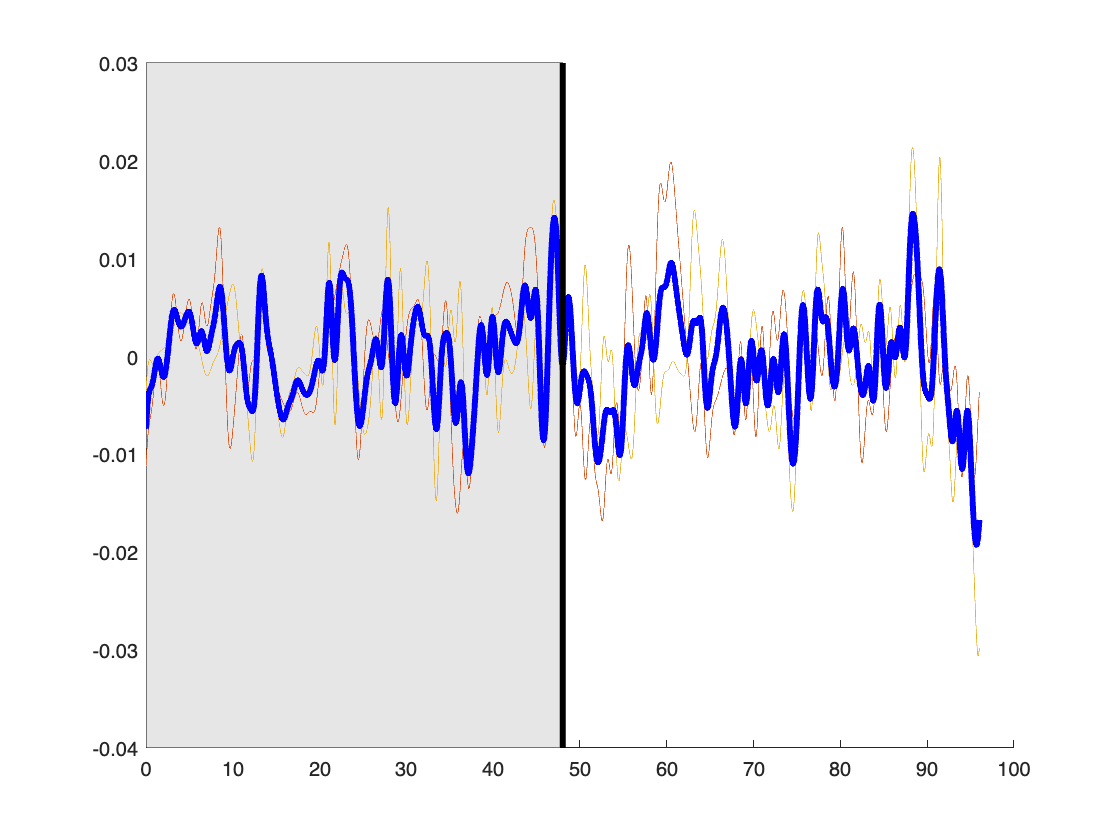

k = 8

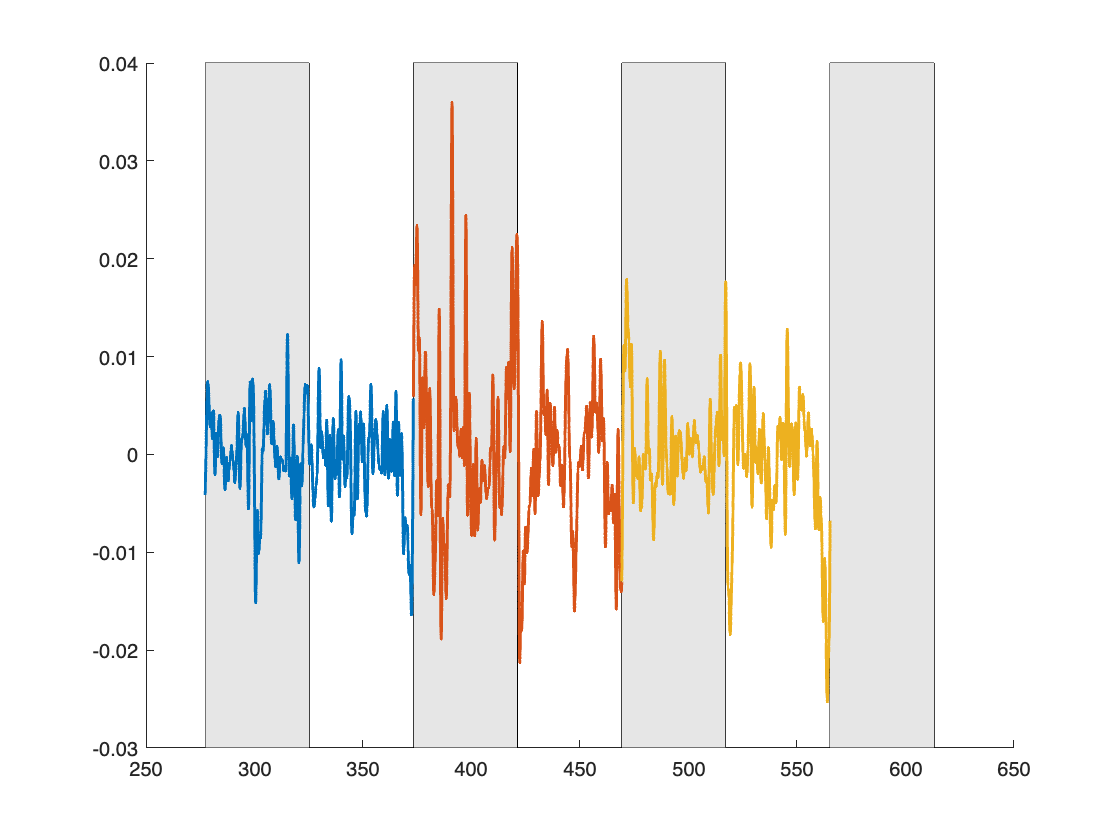

ReFs = 20;
ld = 48;
%48:48 LD
foureightidx = [3 4 5 44 80 81 82 106];%[3 4 5 44 80 81 82 106]
                    %45 shit data - noise issues maybe
                    %46 left out for now - bit messy not too bad
                    %83 single day - kinda messy but not too bad
                    %102 single day (starts with light)
                    %107 messy
    
    for k = 1:length(foureightidx)
        k
        foureightdark(k).day = KatieRegobwDayDessemblerhour(kg(foureightidx(k)), 1, ReFs, 3, k);
       % foureightlight(k).day = KatieRegobwDayDessemblerhour(kg(foureightidx(k)), 1, ReFs, 4);
    end

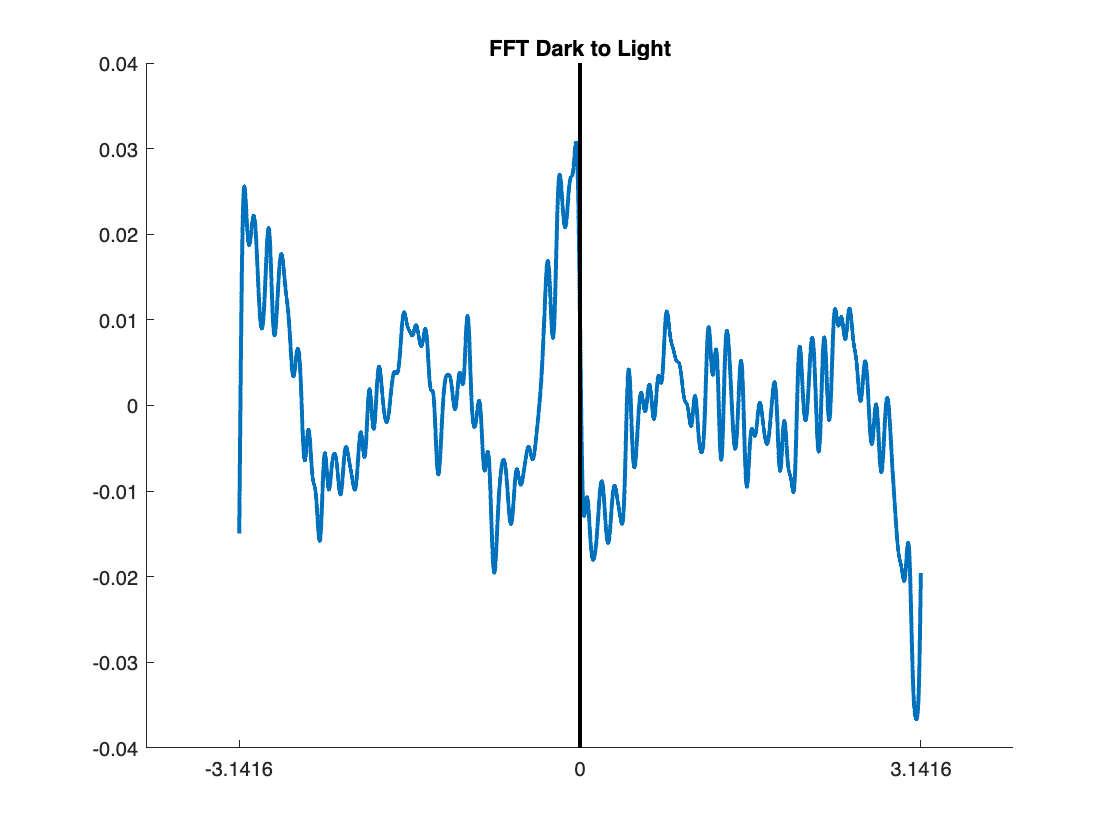


    [hourtim, meanofexperimentmeans, hourampmax, ~] = k_fftdaymovabovemeans(foureightdark);


%plot
figure(317); clf; title('FFT Dark to Light'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};

    
      
        %ld(j,:) = dark(j).ld;
        crosshour = (2*pi) / (2 * ld);
        plot((hourtim .* crosshour)-pi, meanofexperimentmeans, 'LineWidth', 2)
       
  
    plot([0,0], ylim, 'k-', 'LineWidth', 2);